## Questão 1

Dados

VH=0.7;    
eta = 1.05;   
CLalpha=4.1;  %1/rad
St=7;         %m²
alpha=10;     %grau
CmCG = -0.33 - 0.044*alpha

CmCG =         -0.77

Para equilibrar os momentos no avião, é necessário que o coeficiente de momento seja igual a zero, dessa forma a contribuição do profundor para o coeficiente de momento somado ao $C_{\textrm{mCG}}$ já calculado deve ser nulo.


$$C_{mCG} + C_{m\delta e}\delta_e=0$$


Como o problema pede a area necessária do profundor, nos fornecendo os batentes do mesmo, concluimos que deveria ser calculada a area minima necessária para estabilizar a aeronave com o profundor no batente.


$$\tau = \frac{C_{mCG}}{\eta V_H C_{L_{\alpha,t}}\delta_e}$$


deltaE = deg2rad([-20]);
tau = CmCG./(eta*VH*CLalpha*deltaE)

tau =         0.732

Se = @(tau) St.*(0.342.*tau.^4 - 0.0287.*tau.^3 + 0.6028.*tau.^2 + 0.239.*tau);
Se_res = Se(tau)

Se_res =        4.0942

Seria necessária uma area de 4.0942 m² para equilibrar o avião em um pouso com o ângulo de ataque de 10° e o profundor no batente de -20°.

## Questão 2

X_ca_wb = 0.235;
St_S    = 0.25;
eta     = 0.95;
VH      = 0.42;
dedalpha= 0.35;
CLalpha_wb = 0.095;
CLalpha_t = 0.075;
CLalpha = CLalpha_wb + eta*St_S*CLalpha_t*(1-dedalpha)

CLalpha =       0.10658

xn = X_ca_wb + eta*VH*(1-dedalpha)*CLalpha_t/CLalpha

xn =       0.41751

## Questão 3

Che_alphat = -0.0045;
Che_deltae = -0.0065;
Che_0 = -0.005;
SeSt = 0.35;

syms tau
eq1 = (0.342.*tau.^4 - 0.0287.*tau.^3 + 0.6028.*tau.^2 + 0.239.*tau) == SeSt

$$eq1 = 0.3420\,\tau^{4}-0.0287\,\tau^{3}+0.6028\,\tau^{2}+0.2390\,\tau =0.3500$$

tau = solve(eq1, tau)

$$tau = \left(\begin{array}{c} 0.5587\\ -0.8004\\ 0.1628-1.5040\,\mathrm{i}\\ 0.1628+1.5040\,\mathrm{i} \end{array}\right)$$

tau = double(tau(1))

tau =        0.5587

dClt_ddeltae = tau*CLalpha_t;
Cl_deltae = eta * St_S * dClt_ddeltae;
f = 1 - dClt_ddeltae*Che_alphat/(CLalpha_t * Che_deltae)

f =       0.61321

F = 1 - Cl_deltae*Che_alphat/(CLalpha*Che_deltae) * (1 - dedalpha)

F =       0.95798


xn = X_ca_wb + f/F * eta * VH * (1 - dedalpha)*CLalpha_t/CLalpha

xn =       0.35182

## Questão 4

Dados da questão

clear 
S = 16.21;  %m²
rho_0 = 1.225;
g = 9.81;
VE = [40.7 48.7 56.3 69.3 39.8 46.9 55 67.5 38.9 46 54.5 68];   %m/s
W = [1656 1650 1649 1646 1466 1463 1461 1458 1293 1290 1288 1286];  %kg
it = [-1.5 0 1 2 -4.5 -2 -0.3 1 -7.2 -3.5 -1.5 0];                       %graus
x_cg = [238.5 238.5 238.5 238.5 220.5 220.5 220.5 220.5 204.3 204.3 204.3 204.3]; %cm

Como o voo é reto e nivelado, $W = L = \frac{1}{2}\rho V^2 SC_L$, portanto


$$C_L = \frac{2W}{\rho V^2 S}$$


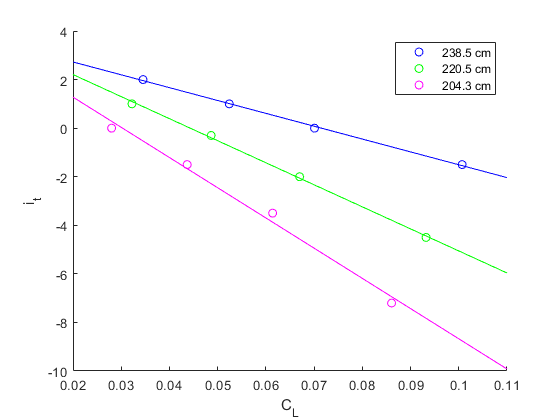

Cl = 2.*W./(rho_0.*VE.^2*S);
Cl1 = Cl(1:4);
it1 = it(1:4);
Cl2 = Cl(5:8);
it2 = it(5:8);
Cl3 = Cl(9:12);
it3 = it(9:12);


[fitresult1, gof1] = fit_top(Cl1, it1);
[fitresult2, gof2] = fit_top(Cl2, it2);
[fitresult3, gof3] = fit_top(Cl3, it3);
x = 0.02:0.001:0.11;
figure
hold on
plot(Cl1, it1, 'bo')
plot(x, fitresult1(x), 'b')
plot(Cl2, it2, 'go')
plot(x, fitresult2(x), 'g')
plot(Cl3, it3, 'mo')
plot(x, fitresult3(x), 'm')
hold on
xlabel('C_L')
ylabel('i_t')
legend('238.5 cm', '', '220.5 cm', '', '204.3 cm')
hold off

ditdCl = [fitresult1.p1 fitresult2.p1 fitresult3.p1];
xcgs = flip(unique(x_cg));
[fitresulttop, goftop] = fit_top(xcgs, ditdCl);
xn = fsolve(fitresulttop, 0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xn =        263.84

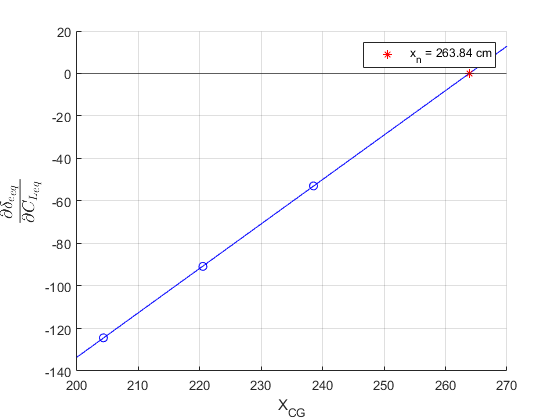

figure
hold on
plot(xcgs, ditdCl, 'bo')
plot(200:270, fitresulttop(200:270), 'b')
yline(0)
plot(xn, 0, 'r*')
grid on
str = sprintf('x_n = %.2f cm', xn);
legend('', '', '', str)
xlabel('X_{CG}')
ylabel('$\frac{\partial \delta_{e_{eq}}}{\partial C_{L_{eq}}}$', 'FontSize', 18,'interpreter','latex')

## Questão 5

format shortG
clear all
close all
clc

aircraft = struct('S',116, ...
    'c',3.862, ...
    'b',32.757,...
    'm',55788, ...
    'Ixx',8.215e5, ...
    'Iyy',3.344e6,...
    'Izz',4.057e6, ...
    'Ixz',1.789e5,...
    'i_l_deg',2, ...
    'i_r_deg',2, ...
    'tau_l_deg', 1.5,...
    'tau_r_deg', -1.5,...
    'x_l',4.899, ...
    'y_l',-5.064,...
    'z_l',1.435,...
    'x_r',4.899, ...
    'y_r',5.064,...
    'z_r',1.435,...
    'Tmax',100e3, ...
    'n_rho',0.8, ...
    'g', 9.80665);

%Condição de Operação - Cruzeiro
trim_par = struct('V',230.15, ...
    'h',11582.4, ...
    'gamma_deg',0, ...
    'thetadot_deg_s',0, ...
    'psidot_deg_s',0);

Xtest = [
    250
    2
    5
    5
    5000
    0
    2
    10
    10
    15
    10
    0
    ];
Utest = [0.5; 0.5; -5; 5; 5; 5];
dynamics(0,Xtest,Utest, aircraft, 0, 0)

ans =       -1.1166
      0.97898
       29.496
       2.3193
       11.699
        244.6
      -14.239
       11.368
      -138.48
      -29.925


%  aero_databank(Xtest,Utest, aircraft, 0, 0)

### a) Resultados obtidos para as variáveis de estado, de controle e de sáida na condição de equilíbrio.

options = optimset('Display','iter','TolX',1e-10,'TolFun',1e-10);
x_eq_0 = zeros(13,1);
x_eq_0(1) = trim_par.V;
x_eq = fsolve(@trim_function,x_eq_0,options,trim_par, aircraft, 0, 0);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0         14         2.55982                          7.33               1
     1         28         0.47507              1          0.705               1
     2         42     0.000173362        1.62056        0.00821             2.5
     3         56     6.17015e-14      0.0158672       2.05e-07            4.05
     4         70     1.80289e-28    5.31626e-07       6.33e-14            4.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

[~,X_eq,U_eq, Y_eq] = trim_function(x_eq,trim_par,aircraft, 0, 0);
    
trim_output.X_eq = X_eq;
trim_output.U_eq = U_eq;
trim_output.Y_eq = Y_eq;

fprintf('----- Cruze FLIGHT CONDITION -----\n\n');

----- Cruze FLIGHT CONDITION -----



fprintf('   %-10s = %10.4f %-4s\n','gamma',trim_par.gamma_deg,'deg');

   gamma      =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','theta_dot',trim_par.thetadot_deg_s,'deg/s');

   theta_dot  =     0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','psi_dot',trim_par.psidot_deg_s,'deg/s');

   psi_dot    =     0.0000 deg/s


fprintf('\n');
fprintf('   %-10s = %10.2f %-4s\n','V',X_eq(1),'m/s');

   V          =     230.15 m/s 


fprintf('   %-10s = %10.4f %-4s\n','alpha',X_eq(2),'deg');

   alpha      =     1.7686 deg 


fprintf('   %-10s = %10.4f %-4s\n','q',X_eq(3),'deg/s');

   q          =     0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','theta',X_eq(4),'deg');

   theta      =     1.7686 deg 


fprintf('   %-10s = %10.1f %-4s\n','h',X_eq(5),'m');

   h          =    11582.4 m   


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','beta',X_eq(7),'deg');

   beta       =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','phi',X_eq(8),'deg');

   phi        =    -0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','p',X_eq(9),'deg/s');

   p          =    -0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','r',X_eq(10),'deg/s');

   r          =    -0.0000 deg/s


fprintf('   %-10s = %10.4f %-4s\n','psi',X_eq(11),'deg');

   psi        =    -0.0000 deg 


fprintf('\n');
fprintf('   %-10s = %10.2f %-4s\n','throttle_l',U_eq(1)*100,'%');

   throttle_l =      42.08 %   


fprintf('   %-10s = %10.2f %-4s\n','throttle_r',U_eq(2)*100,'%');

   throttle_r =      42.08 %   


fprintf('   %-10s = %10.2f %-4s\n','Thrust_L',Y_eq(2),'N');

   Thrust_L   =   14808.02 N   


fprintf('   %-10s = %10.2f %-4s\n','Thrust_R',Y_eq(3),'N');

   Thrust_R   =   14808.02 N   


fprintf('   %-10s = %10.4f %-4s\n','i_t',U_eq(3),'deg');

   i_t        =    -0.4495 deg 


fprintf('   %-10s = %10.4f %-4s\n','delta_e',U_eq(4),'deg');

   delta_e    =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','delta_a',U_eq(5),'deg');

   delta_a    =     0.0000 deg 


fprintf('   %-10s = %10.4f %-4s\n','delta_r',U_eq(6),'deg');

   delta_r    =     0.0000 deg 


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','Mach',Y_eq(4),'');

   Mach       =     0.7800     


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','C_D',Y_eq(5),'');

   C_D        =     0.0290     


fprintf('   %-10s = %10.4f %-4s\n','C_L',Y_eq(6),'');

   C_L        =     0.5345     


fprintf('   %-10s = %10.4f %-4s\n','C_m',Y_eq(7),'');

   C_m        =    -0.0121     


fprintf('\n');
fprintf('   %-10s = %10.4f %-4s\n','C_Y',Y_eq(8),'');

   C_Y        =    -0.0000     


fprintf('   %-10s = %10.4f %-4s\n','C_l',Y_eq(9),'');

   C_l        =    -0.0000     


fprintf('   %-10s = %10.4f %-4s\n','C_n',Y_eq(10),'');

   C_n        =    -0.0000     


fprintf('\n');

#### Margem estática a manche fixo


$$K_n = -\frac{C_{m_{\alpha,CG}}}{C_{L_\alpha}}$$


Cm_alpha = -0.0402; %Tabela 3
CL_alpha = 0.133;   %Tabela 2
Kn = -(Cm_alpha/CL_alpha)*100

Kn =        30.226

#### Autovalores da dinâmica linearizada

lin_output = struct('A',zeros(length(X_eq),length(X_eq)),...
    'B',zeros(length(X_eq),length(U_eq)),...
    'C',zeros(length(Y_eq),length(X_eq)),...
    'D',zeros(length(Y_eq),length(U_eq)));

step_val = 1e-5;

X_eq = trim_output.X_eq;
U_eq = trim_output.U_eq;
Y_eq = trim_output.Y_eq;

A = zeros(length(X_eq),length(X_eq));
C = zeros(length(Y_eq),length(X_eq));
for j=1:length(X_eq)
    dX = zeros(length(X_eq),1);
    dX(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq+dX,U_eq, aircraft, 0, 0);
    [Xdot_m,Y_m] = dynamics(0,X_eq-dX,U_eq, aircraft, 0, 0);
    A(:,j) = (Xdot_p - Xdot_m)/(2*dX(j));
    C(:,j) = (Y_p - Y_m)/(2*dX(j));
end

B = zeros(length(X_eq),length(U_eq));
D = zeros(length(Y_eq),length(U_eq));
for j=1:length(U_eq)
    dU = zeros(length(U_eq),1);
    dU(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq,U_eq+dU, aircraft, 0, 0);
    [Xdot_m,Y_m] = dynamics(0,X_eq,U_eq-dU, aircraft, 0, 0);
    B(:,j) = (Xdot_p - Xdot_m)/(2*dU(j));
    D(:,j) = (Y_p - Y_m)/(2*dU(j));
end

lin_output.A = A;
lin_output.B = B;
lin_output.C = C;
lin_output.D = D;

eigval = eig(lin_output.A([1:5 7:11],[1:5 7:11]))

eigval =             0 +          0i
     -0.58612 +     1.6377i
     -0.58612 -     1.6377i
   -0.0010993 +   0.066044i
   -0.0010993 -   0.066044i
   -0.0011109 +          0i
       -2.176 +          0i
     -0.11181 +      1.673i
     -0.11181 -      1.673i
    -0.008708 +          0i


damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -5.86e-01 + 1.64e+00i     3.37e-01       1.74e+00          1.71e+00    
 -5.86e-01 - 1.64e+00i     3.37e-01       1.74e+00          1.71e+00    
 -1.10e-03 + 6.60e-02i     1.66e-02       6.61e-02          9.10e+02    
 -1.10e-03 - 6.60e-02i     1.66e-02       6.61e-02          9.10e+02    
 -1.11e-03                 1.00e+00       1.11e-03          9.00e+02    
 -2.18e+00                 1.00e+00       2.18e+00          4.60e-01    
 -1.12e-01 + 1.67e+00i     6.67e-02       1.68e+00 

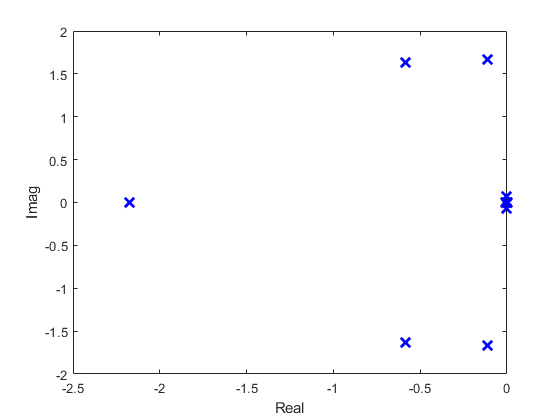

figure
plot(real(eig(A)),imag(eig(A)),'bx','MarkerSize',10,'LineWidth',2)
xlabel('Real')
ylabel('Imag')

Os três primeiros autovalores correspondem as variáveis de estado $x
$, $\psi$ e $y$ e dizemos que são "estados ignoráveis" para fins de análise de estabildade.

O par complexo (-1.1E-03 $\pm$ i6.6E-02) é o par complexo mais próximo da origem do plano complexo e corresponde a fugóide.

O par complexo (-5.86E-01 $\pm$ i1.64) é o par complexo mais distante da origem do plano complexo e corresponde ao modo de curto período.

O autovalor -1.1E-03 corresponde a pequena influência da altitude nas cargas aerodinâmicas e/ou propulsivas.

O par complexo (-1.12E-01 $\pm$ i1.67) corresponde ao Dutch roll.

O autovalor -2.18 corresponde ao modo de rolamento puro.

O autovalor -8.71E-03 corresponde ao modo espiral.

### b) Doublet

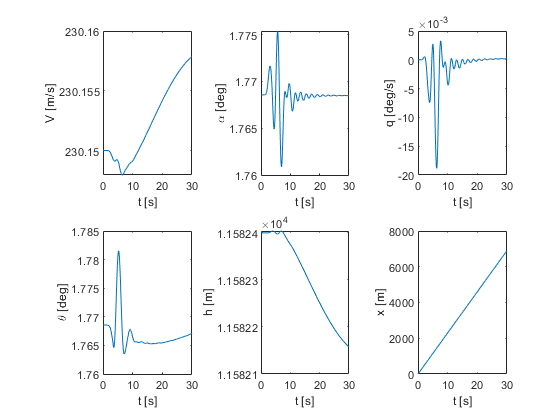

dt = 0.050;
tF = 30;

X0 = trim_output.X_eq;
U0 = trim_output.U_eq;

T = 0:dt:tF;

[X,Y] = ode4xy(@throttle_doublet,T,X0,U0, aircraft, 0, 0);

U = Y(:,11:16);
Y = Y(:,1:10);

figure
plot_long

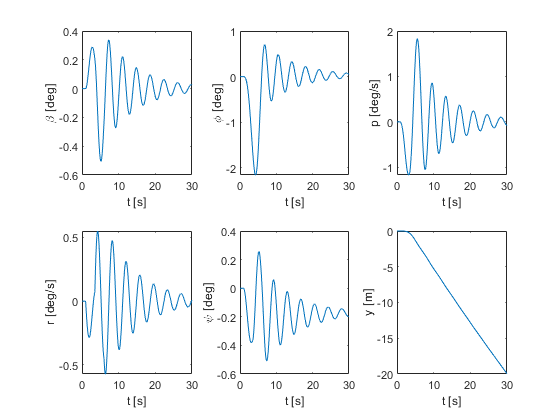

figure
plot_latdir

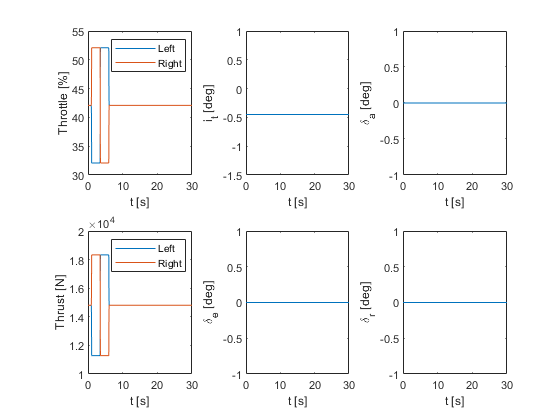

figure
plot_controls

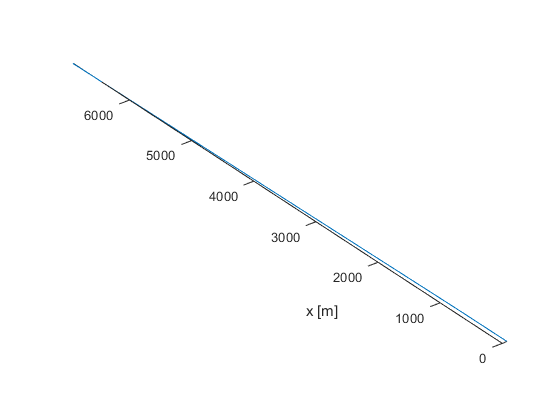

figure
plot_path

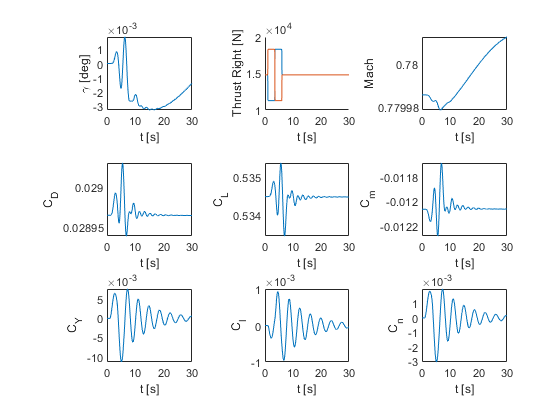

figure
plot_outputs

O doublet de propulsão causou um leve desvio na trajetória do avião, evidenciado pelo gráfico de trajetória. Ele também apresentou o efeito análogo aquele de um doublet de rudder iniciando um modo de dutch roll que é bastante amortecido dentro dos 30s simulados, que pode ser observado pelos gráficos das variáveis de estado látero-direcionais.

### c) Variação do CG

No material de aula podemos encontrar a equação do $C_{L_{\alpha,wb}}$ e do $C_{L_{0,wb}}
$

$C_{L_{\alpha,wb}} = C_{L_{\alpha}} - \eta\frac{S_t}{S}\left (1 - \frac{\partial \epsilon}{\partial \alpha} \right )$             (1)

$C_{L_{0,wb}} = C_{L_{0}} + \eta\frac{S_t}{S}\left (C_{L_{\alpha,t}}\epsilon_0 -  C_{L_{0,t}} \right)$    (2)

Sabendo que 

 (3)

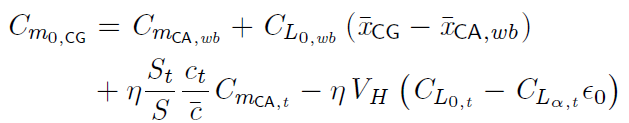 (4)

Substituindo a Equação (1) na (2) e a (3) na (4) e usando $\bar{x}_{CG}$ como $\bar{x}_{CG} + \Delta\bar{x}_{CG}$ têm-se


$$\Delta C_{m_\alpha} = C_{L_\alpha}\Delta \bar{x}_{CG}$$



$$\Delta C_{m_0} = C_{L_0}\Delta \bar{x}_{CG}$$


### d-1) 

Sabendo que a margem estática é $K_{n_{old}} = \bar{x}_n - \bar{x}_{CG}$

Kn_old = Kn/100

Kn_old =       0.30226

A margem estática com o centro de gravidade alterado é $K_{n_{new}} = \bar{x}_{n} - (\bar{x}_{CG} + \Delta \bar{x}_{CG})$

Sabendo que o ponto neutro é constante, 


$$K_{n_{old}} + \bar{x}_{CG} = K_{n_{new}} + \bar{x}_{CG} +\Delta \bar{x}_{CG}$$


Portanto,


$$\Delta \bar{x}_{CG} = K_{n_{old}} -  K_{n_{new}}$$


Kn_new = -5/100; 
deltaXcg = Kn_old - Kn_new

deltaXcg =       0.35226

flag = 1; %Letra d)
options = optimset('Display','iter','TolX',1e-10,'TolFun',1e-10);
x_eq_0 = zeros(13,1);
x_eq_0(1) = trim_par.V;
x_eq = fsolve(@trim_function,x_eq_0,options,trim_par, aircraft, flag, deltaXcg);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0         14         72.9775                          49.6               1
     1         28         7.42704              1           14.3               1
     2         42      0.00079137        2.35751         0.0178             2.5
     3         56     1.63797e-12       0.033512       1.06e-06            5.89
     4         70     1.86798e-23    2.56435e-06       4.32e-12            5.89

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

[~,X_eq,U_eq, Y_eq] = trim_function(x_eq,trim_par,aircraft, flag, deltaXcg);
    
trim_output_deltaX.X_eq = X_eq;
trim_output_deltaX.U_eq = U_eq;
trim_output_deltaX.Y_eq = Y_eq;

fprintf('   %-10s = %10.4f %-4s\n','alpha',X_eq(2),'deg');

   alpha      =     1.4586 deg 


fprintf('   %-10s = %10.4f %-4s\n','i_t',U_eq(3),'deg');

   i_t        =     1.6896 deg 


fprintf('   %-10s = %10.2f %-4s\n','throttle_l',U_eq(1)*100,'%');

   throttle_l =      39.18 %   


fprintf('   %-10s = %10.2f %-4s\n','throttle_r',U_eq(2)*100,'%');

   throttle_r =      39.18 %   


fprintf('   %-10s = %10.2f %-4s\n','Thrust_L',Y_eq(2),'N');

   Thrust_L   =   13787.97 N   


fprintf('   %-10s = %10.2f %-4s\n','Thrust_R',Y_eq(3),'N');

   Thrust_R   =   13787.97 N   


Linearizando o modelo em torno das condições de equilíbrio para margem estática de -5%.

X_eq = trim_output_deltaX.X_eq;
U_eq = trim_output_deltaX.U_eq;
Y_eq = trim_output_deltaX.Y_eq;

lin_output = struct('A',zeros(length(X_eq),length(X_eq)),...
    'B',zeros(length(X_eq),length(U_eq)),...
    'C',zeros(length(Y_eq),length(X_eq)),...
    'D',zeros(length(Y_eq),length(U_eq)));

step_val = 1e-5;

A = zeros(length(X_eq),length(X_eq));
C = zeros(length(Y_eq),length(X_eq));
for j=1:length(X_eq)
    dX = zeros(length(X_eq),1);
    dX(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq+dX,U_eq, aircraft, flag, deltaXcg);
    [Xdot_m,Y_m] = dynamics(0,X_eq-dX,U_eq, aircraft, flag, deltaXcg);
    A(:,j) = (Xdot_p - Xdot_m)/(2*dX(j));
    C(:,j) = (Y_p - Y_m)/(2*dX(j));
end

B = zeros(length(X_eq),length(U_eq));
D = zeros(length(Y_eq),length(U_eq));
for j=1:length(U_eq)
    dU = zeros(length(U_eq),1);
    dU(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq,U_eq+dU, aircraft, flag, deltaXcg);
    [Xdot_m,Y_m] = dynamics(0,X_eq,U_eq-dU, aircraft, flag, deltaXcg);
    B(:,j) = (Xdot_p - Xdot_m)/(2*dU(j));
    D(:,j) = (Y_p - Y_m)/(2*dU(j));
end

lin_output.A = A;
lin_output.B = B;
lin_output.C = C;
lin_output.D = D;

[eigvec, eigval] = eig(A);
eigval = diag(eigval)

eigval =             0 +          0i
            0 +          0i
            0 +          0i
      -1.2254 +          0i
      0.17477 +          0i
     -0.03333 +    0.11479i
     -0.03333 -    0.11479i
   -0.0009968 +          0i
      -2.1884 +          0i
     -0.10541 +     1.6677i


eigval(eigval > 0)

ans =       0.17477

isstable(ss(A, B, C, D))

ans = logical
   0

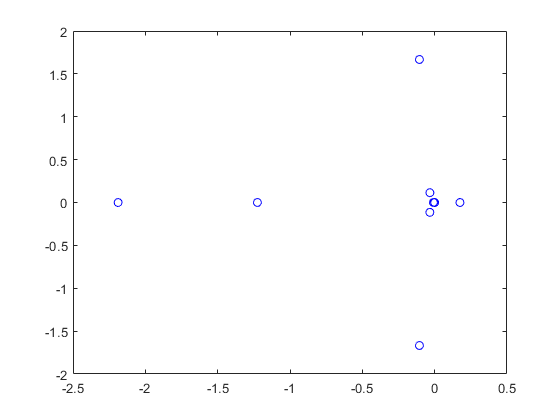

figure
plot(real(eigval), imag(eigval), 'bo')

Analisando os autovalores da matriz A do modelo dinâmico linearizado, é possível ver que existe um polo no semi-plano direito que torna o avião instável. Essa dinâmica fica evidente quando adicionamos uma pequena perturbação a um dos estados do avião, a partir do equilíbrio.

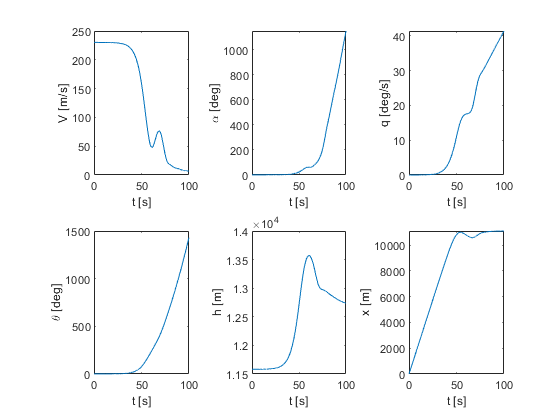

dt = 0.050;
tF = 100;

X0 = trim_output_deltaX.X_eq;
U0 = trim_output_deltaX.U_eq;
X0(2) = X0(2)*1.01;
%Uma alteração de 1% no angulo de ataque da condição de equilibrio ja desestabiliza o sistema

T = 0:dt:tF;

[X,Y] = ode4xy(@dynamics,T,X0,U0, aircraft, flag, deltaXcg);

U = repmat(U0.',length(T),1);

plot_long

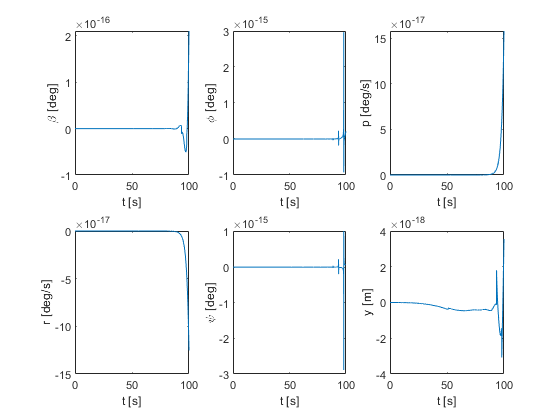

plot_latdir

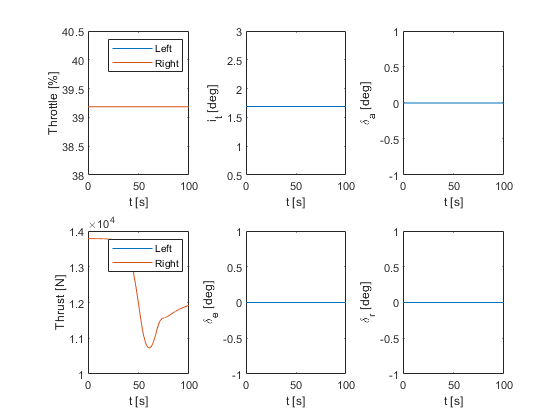

plot_controls

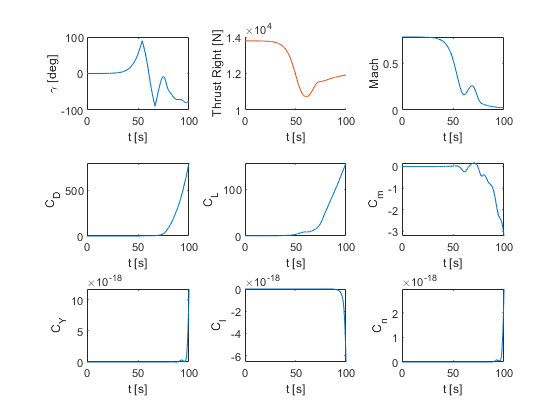

plot_outputs

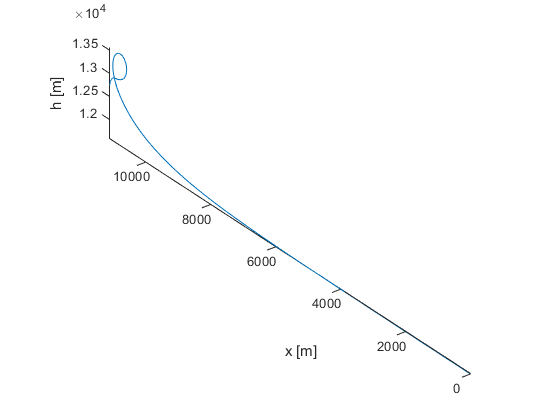

plot_path

### d-2)

%Variando a margem estática de -10 a 30 com um passo de 5
Kn_new = (-10:0.1:30)./100; 
deltaXcg = Kn_old - Kn_new;
flag = 1; %Letra d)
options = optimset('Display','off','TolX',1e-10,'TolFun',1e-10);
x_eq_0 = zeros(13,1);
x_eq_0(1) = trim_par.V;
T_tot = zeros(1, length(Kn_new)); 
alpha_d = zeros(1, length(Kn_new));
i_t_d = zeros(1, length(Kn_new));   
for i=1:length(Kn_new)
    x_eq = fsolve(@trim_function,x_eq_0,options,trim_par, aircraft, flag, deltaXcg(i));
    [~,X_eq,U_eq, Y_eq] = trim_function(x_eq,trim_par,aircraft, flag, deltaXcg(i));
    T_tot(i) = Y_eq(2) + Y_eq(3);
    alpha_d(i) = X_eq(2);
    i_t_d(i) = U_eq(3);
end

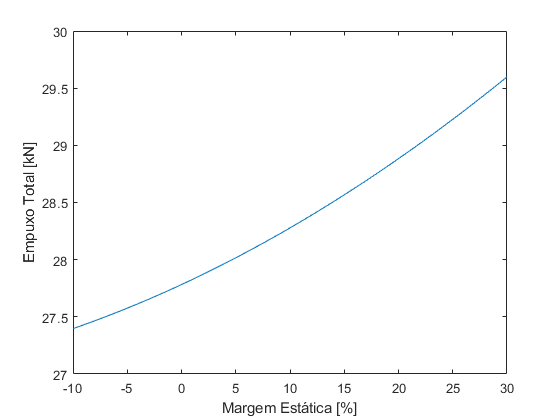

figure
plot(Kn_new.*100, T_tot./1e3)
ylabel('Empuxo Total [kN]')
xlabel('Margem Estática [%]')

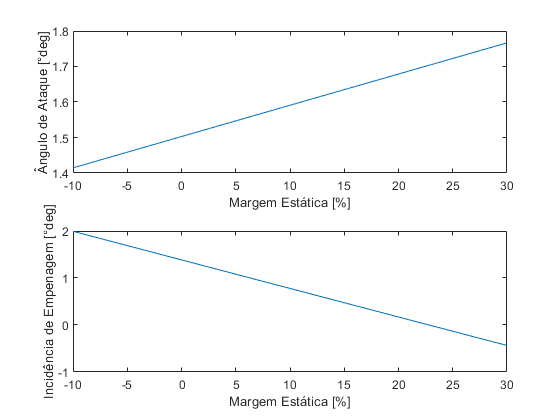

figure
subplot 211
plot(Kn_new.*100, alpha_d)
xlabel('Margem Estática [%]')
ylabel('Ângulo de Ataque [°deg]')
subplot 212
plot(Kn_new.*100, i_t_d)
xlabel('Margem Estática [%]')
ylabel(['Incidência de Empenagem [°deg]'])

Para manter o avião em equilíbrio longitudinal com a margem estática maior, é necessário que o avião voe com ângulo de ataque maior e incidência da empenagem horizontal menor para compensar o deslocamento do centro de gravidade. Com um ângulo de ataque maior, a componente do empuxo do motor no sentido do deslocamento do avião fica menor, exigindo um aumento do empuxo para manter a condição de equilíbrio.

Se o consumo de combustível é proporcional a tração, em uma condição de margem estática menor, onde menos tração é requerida, o avião irá consumir menos combustível.

### e) LGR

Kn_new = -5/100;
deltaXcg = Kn_old - Kn_new;
flag = 1; %Letra d)

X_eq = trim_output_deltaX.X_eq;
U_eq = trim_output_deltaX.U_eq;
Y_eq = trim_output_deltaX.Y_eq;

lin_output = struct('A',zeros(length(X_eq),length(X_eq)),...
    'B',zeros(length(X_eq),length(U_eq)),...
    'C',zeros(length(Y_eq),length(X_eq)),...
    'D',zeros(length(Y_eq),length(U_eq)));

step_val = 1e-5;

A = zeros(length(X_eq),length(X_eq));
C = zeros(length(Y_eq),length(X_eq));
for j=1:length(X_eq)
    dX = zeros(length(X_eq),1);
    dX(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq+dX,U_eq, aircraft, flag, deltaXcg);
    [Xdot_m,Y_m] = dynamics(0,X_eq-dX,U_eq, aircraft, flag, deltaXcg);
    A(:,j) = (Xdot_p - Xdot_m)/(2*dX(j));
    C(:,j) = (Y_p - Y_m)/(2*dX(j));
end

B = zeros(length(X_eq),length(U_eq));
D = zeros(length(Y_eq),length(U_eq));
for j=1:length(U_eq)
    dU = zeros(length(U_eq),1);
    dU(j) = step_val;
    [Xdot_p,Y_p] = dynamics(0,X_eq,U_eq+dU, aircraft, flag, deltaXcg);
    [Xdot_m,Y_m] = dynamics(0,X_eq,U_eq-dU, aircraft, flag, deltaXcg);
    B(:,j) = (Xdot_p - Xdot_m)/(2*dU(j));
    D(:,j) = (Y_p - Y_m)/(2*dU(j));
end

lin_output.A = A;
lin_output.B = B;
lin_output.C = C;
lin_output.D = D;

ksi = 0.7;
wn = 3;

polos = [-ksi*wn + 1j*wn*sqrt(1-ksi^2), -ksi*wn - 1j*wn*sqrt(1-ksi^2)]

polos =          -2.1 +     2.1424i         -2.1 -     2.1424i


A_sp = A(2:3,2:3);
B_sp = B(2:3,4);

damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -1.23e+00                 1.00e+00       1.23e+00          8.16e-01    
  1.75e-01                -1.00e+00       1.75e-01         -5.72e+00    
 -3.33e-02 + 1.15e-01i     2.79e-01       1.20e-01          3.00e+01    
 -3.33e-02 - 1.15e-01i     2.79e-01       1.20e-01          3.00e+01    
 -9.97e-04                 1.00e+00       9.97e-04          1.00e+03    
 -2.19e+00                 1.00e+00       2.19e+00          4.57e-01    
 -1.05e-01 + 1.67e+00i     6.31e-02       1.67e+00 

damp(A_sp)

                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
 -1.23e+00     1.00e+00       1.23e+00          8.16e-01    
  1.12e-01    -1.00e+00       1.12e-01         -8.95e+00    


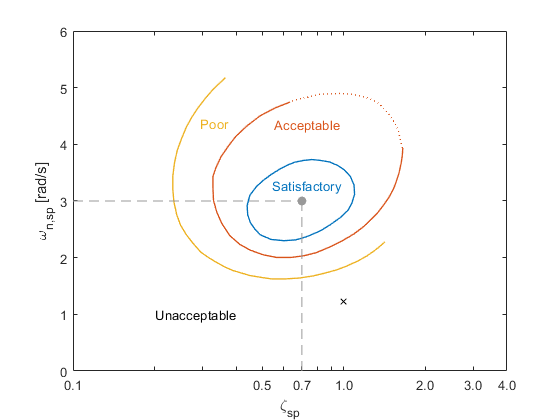

OHara_plot
hold on
[wn,zeta] = damp(A_sp);
plot(zeta(1),wn(1),'kx')

control = rank(ctrb(A_sp, B_sp)) - length(A_sp)

control =      0

%Controlável
K = place(A_sp, B_sp, polos)

K =        -2.605      -1.0602


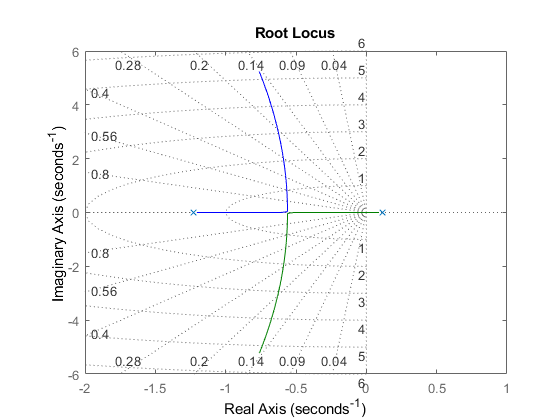

C_alpha = [1 0];
C_q = [0 1];
ss_de_deg_2_alpha_deg = ss(A_sp,B_sp,C_alpha,0);
k = -logspace(-2,1,1000);
figure
rlocus(ss_de_deg_2_alpha_deg,k)
xlim([-2 1])
sgrid

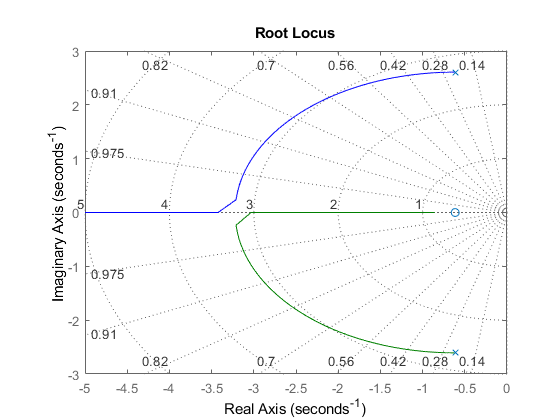

Ac_alpha = A_sp - B_sp*K(1)*C_alpha;

C_q = [0 1];
ss_de_deg_2_q_deg_s = ss(Ac_alpha,B_sp,C_q,0);

k = -logspace(-2,1,1000);
figure
rlocus(ss_de_deg_2_q_deg_s,k)
xlim([-5 0])
sgrid

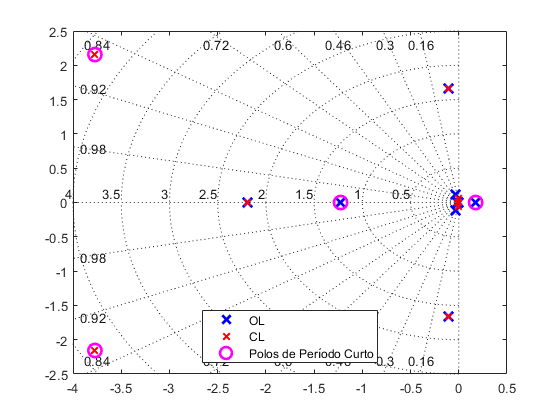

Ac_q = Ac_alpha - B_sp*K(2)*C_q;

C_state = eye(size(A));
C_alpha = C_state(2,:);
C_q = C_state(3,:);
Ac = A - B(:,3)*[K(1) K(2)]*[C_alpha; C_q];
eig_Ac = eig(Ac);
eig_A = eig(A);
markers_x = [eig_A(eig_A>0) real(eig_A(4)) real(max(eig_Ac)) real(max(eig_Ac))];
markers_y = [0 0 imag(max(eig_Ac)) -imag(max(eig_Ac))];
figure
plot(real(eig(A)),imag(eig(A)),'bx','MarkerSize',10,'LineWidth',2)
hold on
plot(real(eig(Ac)),imag(eig(Ac)),'rx','MarkerSize',7,'LineWidth',1.5)
plot(markers_x, markers_y, 'mo', 'MarkerSize', 10,'LineWidth',2)
legend('OL','CL', 'Polos de Período Curto', 'Location', 'South')
set(0,'DefaultLegendAutoUpdate','off')
sgrid

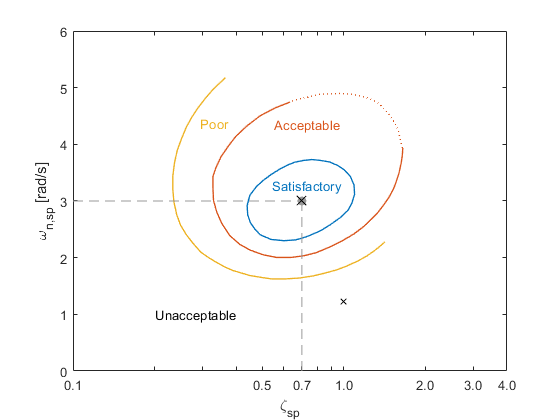

OHara_plot
hold on
[wn_c,zeta_c] = damp(Ac_q);
plot(zeta(1),wn(1),'kx')
plot(zeta_c(1),wn_c(1),'kx','MarkerSize',10)

function [Xdot,Y] = throttle_doublet(t,X,U_eq, aircraft, flag, deltaXcg)
    U = U_eq;
    
    if t>=1 && t<=3.5
        U(1) = U(1) - 0.1;
        U(2) = U(2) + 0.1;
    elseif t>3.5 && t<=6
        U(1) = U(1) + 0.1;
        U(2) = U(2) - 0.1;
    end
    
    [Xdot,Y] = dynamics(t,X,U,aircraft, flag, deltaXcg);
    
    Y = [
        Y
        U
        ];
end

function [fitresult, gof] = fit_top(x, y)
[xData, yData] = prepareCurveData(x, y);

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );
end
